# SMGO: Handling linear inequalities

This simple code is basically the minimal usage case, but with `m` *a priori* known linear inequalities, in the form of $Ax \leq b$, where $A$ is an `m x D` matrix, and $b$ is an `m x 1` column vector.

Clear struct `options` to start this example.

clear options;

We supply the usual required parameters in `options`, but now also including the inequality-relevant matrices `ineq.A` and `ineq.b`.

options.objfun  = @(x)fn_styblinski(x);
options.bounds  = repmat([-5 5], 2, 1);
options.maxiter = 250;
options.ineq.A  = [-1 0.5; 0.5 1];
options.ineq.b  = [1 2]';

Run the SMGO algorithm using the supplied arguments in `options`.

out             = smgo(options);

[INFO] Starting from a random start point.
Running SMGO
Iteration: 1/250, Best z: -25.817
Iteration: 2/250, Best z: -25.817
Iteration: 3/250, Best z: -25.817
Iteration: 4/250, Best z: -25.817
Iteration: 5/250, Best z: -25.817
Iteration: 6/250, Best z: -25.817
Iteration: 7/250, Best z: -31.811
Iteration: 8/250, Best z: -31.811
Iteration: 9/250, Best z: -31.811
Iteration: 10/250, Best z: -31.811
Iteration: 11/250, Best z: -31.811
Iteration: 12/250, Best z: -40.530
Iteration: 13/250, Best z: -41.358
Iteration: 14/250, Best z: -41.358
Iteration: 15/250, Best z: -48.925
Iteration: 16/250, Best z: -48.925
Iteration: 17/250, Best z: -54.522
Iteration: 18/250, Best z: -54.522
Iteration: 19/250, Best z: -57.098
Iteration: 20/250, Best z: -57.098
Iteration: 21/250, Best z: -58.296
Iteration: 22/250, Best z: -58.876
Iteration: 23/250, Best z: -58.876
Iteration: 24/250, Best z: -58.876
Iteration: 25/250, Best z: -65.578
Iteration: 26/250, Best z: -65.578
Iteration: 27/250

Plot the resulting samples distribution throughout the search space.

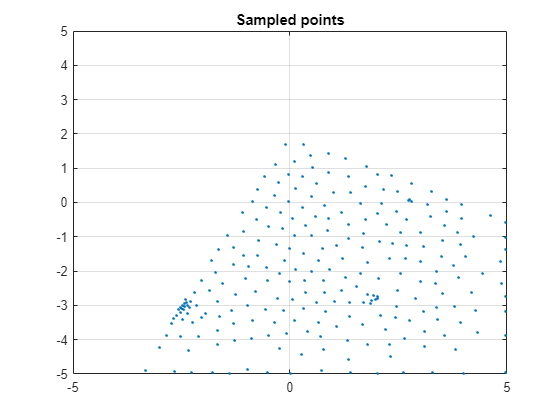

plot(out.hist_x(1,:), out.hist_x(2,:), '.'); 
grid on, title('Sampled points'); xlim([-5 5]); ylim([-5 5]);